## Load LSTM NET from file

clear;
matNetPath = fullfile("models", "LSTM", "Zone8", "LSTM_Zone8_RMSE74.4_20260908_2322.mat");
matNetFile = load(matNetPath);
fprintf("Loaded net from path: %s", matNetPath);

Loaded net from path: models/LSTM/Zone8/LSTM_Zone8_RMSE74.4_20260908_2322.mat

## Net properties

Extract figure title from file name

[~, fileName] = fileparts(matNetPath);
tokens = regexp(fileName, 'LSTM_Zone(\d+)_RMSE([\d.]+)_(\d{8}_\d{4})', 'tokens', 'once');
if ~isempty(tokens)
    figTitle = sprintf("LSTM - Zone %s | RMSE %s kWh", tokens{1}, tokens{2});
    zoneStr = tokens{1};
else
    figTitle = strrep(fileName, "_", " ");
    zoneStr = "Unknown";
end

Plot network architecture

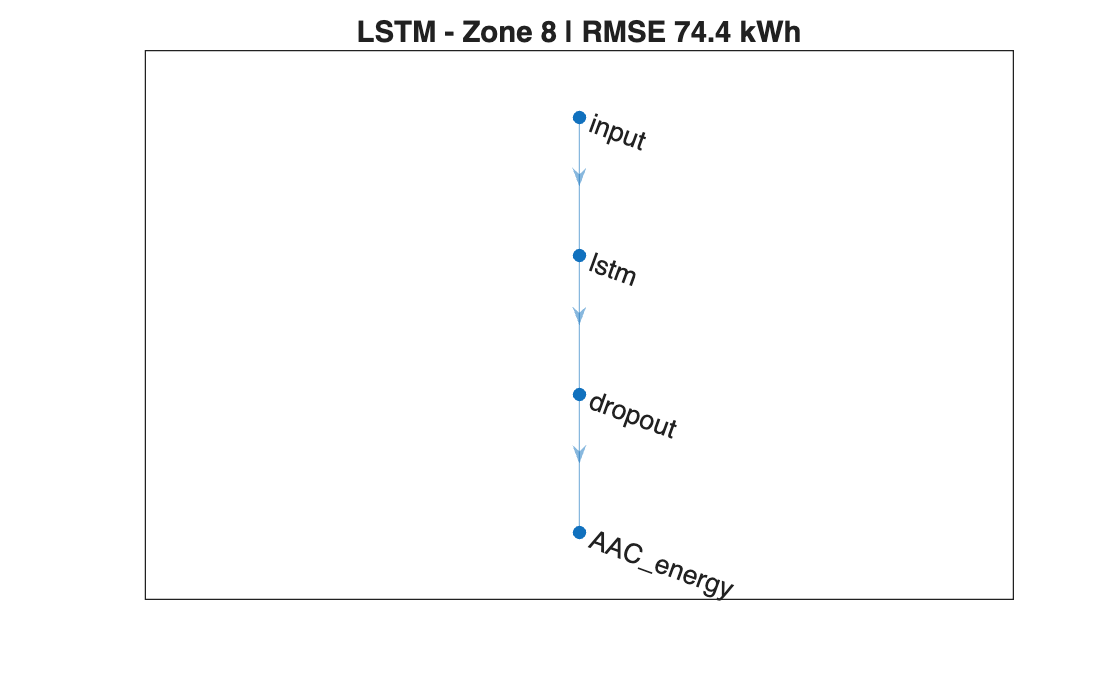

figure
plot(matNetFile.LSTMnet)
title(figTitle, Interpreter="none")

Display learnables table with layer names and tensor dimensions

disp(matNetFile.LSTMnet.Learnables)

       Layer            Parameter              Value      
    ____________    __________________    ________________

    "lstm"          "InputWeights"        {256×5  dlarray}
    "lstm"          "RecurrentWeights"    {256×64 dlarray}
    "lstm"          "Bias"                {256×1  dlarray}
    "AAC_energy"    "Weights"             {  1×64 dlarray}
    "AAC_energy"    "Bias"                {  1×1  dlarray}



Display overall parameter count and input channels

summary(matNetFile.LSTMnet)


   Initialized: true

   Number of learnables: 18k

   Inputs:
      1   'input'   Sequence input with 5 channels



Plot feature importance across input gates

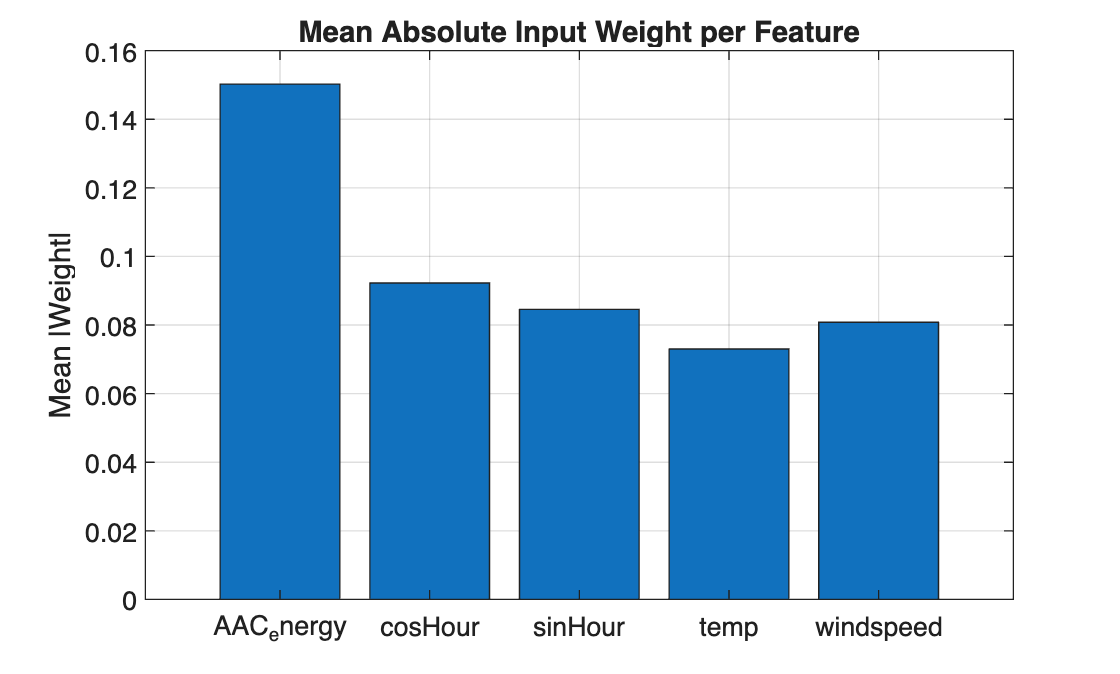

inputWeights = extractdata(matNetFile.LSTMnet.Learnables.Value{1});
featureImpact = mean(abs(inputWeights), 1);
figure
bar(categorical(matNetFile.predictorNames), featureImpact)
title("Mean Absolute Input Weight per Feature")
ylabel("Mean |Weight|")
grid on

Run test inference on normalized sequence

windowSize = 48;
syntheticRaw = repmat(matNetFile.normParams.mu, windowSize, 1);
normalizedSequence = (syntheticRaw - matNetFile.normParams.mu) ./ matNetFile.normParams.sigma;
predictionNormalized = minibatchpredict(matNetFile.LSTMnet, {normalizedSequence}, SequencePaddingDirection="left");
predictedLoad = predictionNormalized * matNetFile.normParams.sigmaTarget + matNetFile.normParams.muTarget;
fprintf("Inference check completed. Predicted load: %.2f kWh\n", predictedLoad);

Inference check completed. Predicted load: 215.17 kWh
